# HTI ColorBox Metameric Light Optimization

%ColorBox Experimental Conditions
%This script calculates the 11-LED pairs that will be used in the
%experiment Investigating the Effects of Daytime Light Exposure with EEG Functional Connectivity Measures

%Written by Elif Naz Gecer 26.10.2021 
%Human Technology Interaction Group, TU/e


%% Initialization
%Load the calibration files
fileCalib=('C:\Users\20204691\Documents\MATLAB\ColorBox LED Calculations\New_ColorBox_Spectra.xlsx');
Spec=xlsread(fileCalib, 'Sheet1', 'A3:K403');
%Calculate alpha-opic irradiances
wl=(380:1:780)'; alpha_vals=nan(4,11);
S026_func_l=S026Functions(wl,'l'); S026_func_m=S026Functions(wl,'m'); S026_func_s=S026Functions(wl,'s'); S026_func_mel=S026Functions(wl,'mel');
alpha_vals(1,:)=sum(Spec(:,:).*S026_func_l); alpha_vals(2,:)=sum(Spec(:,:).*S026_func_m); alpha_vals(3,:)=sum(Spec(:,:).*S026_func_s); alpha_vals(4,:)=sum(Spec(:,:).*S026_func_mel);

%Range of the PWM values is 0-2048 
intensity_settings=2048; 
increment_SLMMel=alpha_vals/intensity_settings;



This example script helps you to use the Optimize Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point `x0` and scale `a` for the optimization.

x0=zeros(1,22)'; 
%distance of the u,v points to each other
Eff_const=0.001362;
dist=0.001;
dist_phot=400;
minLux=200;
inc_Spec=Spec/2048;
XYZ_func=ColorMatchingFunctions(wl,'xyz10');
Km=683.6;
maxlowMEDI=55;
delta_dif=1.05;
delta_delta_dif=1.05;
dist_blackbody=0.005;


alpha_SML=[increment_SLMMel(1:3,:), -1. *increment_SLMMel(1:3,:)];
absolute_val=[alpha_SML;-alpha_SML];

sil_val=0.03;
sil_valS=0.03;
silencing=[sil_valS sil_val sil_val sil_valS sil_val sil_val];

coef_Inc=[1 1 1 1 1 1 1 1 1 1 1,-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1;
    1 1 1 1 1 1 1 1 1 1 1,-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1;
    1 1 1 1 1 1 1 1 1 1 1,-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1; 
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1, 0 0 0 0 0 0 0 0 0 0 0  ];


coef_vector=-1.*[increment_SLMMel(4,:),increment_SLMMel(4,:)].*[0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1 1 ];
% coef_low_mel=[increment_SLMMel(4,:),increment_SLMMel(4,:)].*[ 1 1 1 1 1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0];
% low_mel_level=1;

intcon=[1,2,3,4,5,6,7,8,9,10,11,12, 13,14,15,16,17,18,19,20,21,22];

% RightHandSide=[0 0 0 0 0 0 1];
% a1=-coef_vector;
a1=[increment_SLMMel(4,:) increment_SLMMel(4,:)];
b1=[increment_SLMMel(4,:) -1.*increment_SLMMel(4,:)];

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

This task has objective and nonlinear constraint functions included. To change these functions, edit the function listings below the task.

To change the constraints, select appropriate constraint types and enter values in the input boxes. You might need to enter values in the section containing `x0` above, and run the section to put values in the workspace.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.

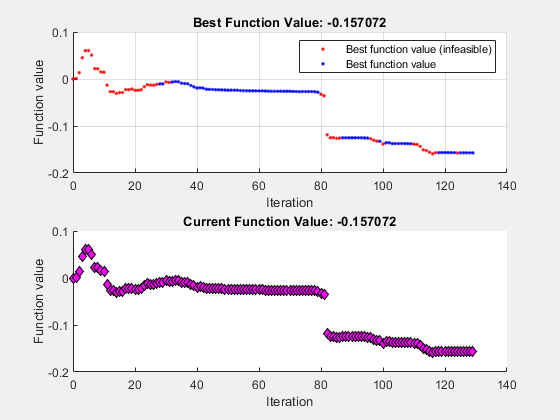


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



% Pass fixed parameters to objfun
objfun = @(x)objectiveFcn(x,a1);

% Pass fixed parameters to confun
confun = @(optimInput)constraintFcn(optimInput,dist,inc_Spec,wl,a1,Km,XYZ_func,dist_phot,minLux,...
    increment_SLMMel,maxlowMEDI,delta_dif,delta_delta_dif,dist_blackbody);

% Set nondefault solver options
options = optimoptions('fmincon','PlotFcn',{'optimplotfvalconstr',...
    'optimplotfval'});

% Solve
[solution,objectiveValue] = fmincon(objfun,x0,absolute_val,silencing,[],[],...
    zeros(size(x0)),repmat(4095,size(x0)),confun,options);


% Clear variables
clearvars objfun confun options

## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution

solution =   212.8754
    0.0070
    0.0056
    0.0096
    0.0290
  152.8253
  135.5601
   89.4016
   90.7212
   16.3215


objectiveValue

objectiveValue = -0.1571

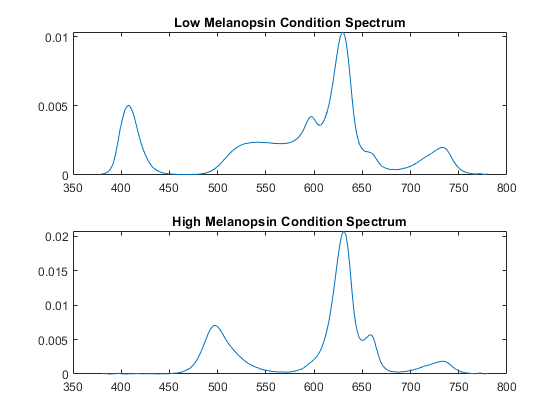


inc_Spec=Spec/2048;

%Rounding the PWM values to integers
sol1=sum(round(solution(1:11))'.*inc_Spec,2);
sol2=sum(round(solution(12:22))'.*inc_Spec,2);


%see the spectra
figure; hold on; subplot(2,1,1);plot(wl,sum(sol1,2)); title('Low Melanopsin Condition Spectrum');
subplot(2,1,2); plot(wl,sum(sol2,2)); title('High Melanopsin Condition Spectrum');

%Check for the differences in alpha-opic irradiances
vals1=sum(solution(1:11)'.*(increment_SLMMel),2);
vals2=sum(solution(12:22)'.*(increment_SLMMel),2);
difval=vals2-vals1;




XYZ_func_10=ColorMatchingFunctions(wl,'xyz10');
%Sol 1 -10degree coordinates
Xcoord10=sum(sol1(:,:).*XYZ_func_10(:,1));Ycoord10=sum(sol1(:,:).*XYZ_func_10(:,2));Zcoord10=sum(sol1(:,:).*XYZ_func_10(:,3));
XYZ10coord1=[Xcoord10;Ycoord10;Zcoord10];
%Sol 2 -10degree coordinates
Xcoord10=sum(sol2(:,:).*XYZ_func_10(:,1));Ycoord10=sum(sol2(:,:).*XYZ_func_10(:,2));Zcoord10=sum(sol2(:,:).*XYZ_func_10(:,3));
XYZ10coord2=[Xcoord10;Ycoord10;Zcoord10];

%Sol 1 -2degree coordinates
XYZ_func=ColorMatchingFunctions(wl,'xyz');
Xcoord=sum(sol1(:,:).*XYZ_func(:,1));Ycoord=sum(sol1(:,:).*XYZ_func(:,2));Zcoord=sum(sol1(:,:).*XYZ_func(:,3));
XYZcoord1=[Xcoord;Ycoord;Zcoord];
%Sol 2 -2degree coordinates
Xcoord=sum(sol2(:,:).*XYZ_func(:,1));Ycoord=sum(sol2(:,:).*XYZ_func(:,2));Zcoord=sum(sol2(:,:).*XYZ_func(:,3));
XYZcoord2=[Xcoord;Ycoord;Zcoord];

%Calculate the ratio of 10/2 -1, we want this difference to be minimized also referrred as delta
%difference
sol_1Y10minusY2=(XYZ10coord1(2)-XYZcoord1(2));
sol_2Y10minusY2=(XYZ10coord2(2)-XYZcoord2(2));

%Calculate the u' v'
upvp1=XYZ2upvp(XYZ10coord1); upvp2=XYZ2upvp(XYZ10coord2);
dist_upvp=sqrt((upvp1(1)-upvp2(1)).^2+(upvp1(2)-upvp2(2)).^2);

%Calculating Duv 
%first upvp needs to be converted to 1960 (u,v)^2
%Q:Does this calculation apply to the 10degree cone fundamentals
u_60=upvp1(1,:); v_60=2*(upvp1(2,:)/3);  Duv1=calcDuv(u_60,v_60);
u_60=upvp2(1,:); v_60=2*(upvp2(2,:)/3);  Duv2=calcDuv(u_60,v_60);

%Calculate the Photopic Illuminance 
Km=683.6; %Maximum luminous efficacy constant
Photopic_Illum1=XYZcoord1(2)*Km;
Photopic_Illum2=XYZcoord2(2)*Km;

%Calculate the Melanopic EDI
%Efficacy function, DIVIDE this value with the melirr to get MelEDI
Eff_const=0.001362;
MEDI1=vals1(4)/Eff_const;
MEDI2=vals2(4)/Eff_const;
diff_MEDI=MEDI2-MEDI1;



View the nonlinear constraint function values at the solution.

% [ccons,ceqcons] = constraintFcn(solution)

## Helper Functions — Local Functions

The following code creates the objective function. Modify this code for your problem.

function f = objectiveFcn(x,a1)
f = sum(a1(1)*x(1)+a1(2)*x(2)+a1(3)*x(3)+a1(4)*x(4)+a1(5)*x(5)+a1(6)*x(6)+a1(7)*x(7)+a1(8)*x(8)+a1(9)*x(9)+a1(10)*x(10)+a1(11)*x(11)-a1(12)*x(12)-a1(13)*x(13)-a1(14)*x(14)-a1(15)*x(15)-a1(16)*x(16)-a1(17)*x(17)-a1(18)*x(18)-a1(19)*x(19)-a1(20)*x(20)-a1(21)*x(21)-a1(22)*x(22));
end

The following code creates the constraint function. Modify this code for your problem.


% inc_Spec=Spec/2048;
% sol1=sum(solution(1:11)'.*inc_Spec,2);
% sol2=sum(solution(12:22)'.*inc_Spec,2);
% 
% %Calculate XYZ
% XYZ_func=ColorMatchingFunctions(wl,'xyz');
% Xcoord=sum(sol1(:,:).*XYZ_func(:,1));Ycoord=sum(sol1(:,:).*XYZ_func(:,2));Zcoord=sum(sol1(:,:).*XYZ_func(:,3));
% XYZcoord1=[Xcoord;Ycoord;Zcoord];
% 
% Xcoord=sum(sol2(:,:).*XYZ_func(:,1));Ycoord=sum(sol2(:,:).*XYZ_difunc(:,2));Zcoord=sum(sol2(:,:).*XYZ_func(:,3));
% XYZcoord2=[Xcoord;Ycoord;Zcoord];



function [c,ceq] = constraintFcn(optimInput,dist,inc_Spec,wl,a1,Km,XYZ_func,dist_phot,minLux,increment_SLMMel,maxlowMEDI,delta_dif,delta_delta_dif,dist_blackbody)
% Example:
% Constrain a solution to the region
% x^2 + y^2 <= 5
% x^2 + y^2 >= 2
% y = x^3

lowmel_cond=optimInput(1:11); highmel_cond=optimInput(12:22);

% lowmel_cond=[x1 x2 x3 x4 x5 x6 x7 x8 x9 x10 x11];
% highmel_cond=[x12 x13 x14 x15 x16 x17 x18 x19 x20 x21 x 22];

sol1=sum(lowmel_cond'.*inc_Spec,2);
sol2=sum(highmel_cond'.*inc_Spec,2);

% XYZ_func=ColorMatchingFunctions(wl,'xyz10');
% Xcoord=sum(sol1(:,:).*XYZ_func(:,1));Ycoord=sum(sol1(:,:).*XYZ_func(:,2));Zcoord=sum(sol1(:,:).*XYZ_func(:,3));
% XYZcoord1=[Xcoord;Ycoord;Zcoord];
% 
% Xcoord=sum(sol2(:,:).*XYZ_func(:,1));Ycoord=sum(sol2(:,:).*XYZ_func(:,2));Zcoord=sum(sol2(:,:).*XYZ_func(:,3));
% XYZcoord2=[Xcoord;Ycoord;Zcoord];

XYZ_func_10=ColorMatchingFunctions(wl,'xyz10');
%Sol 1 -10degree coordinates
Xcoord10=sum(sol1(:,:).*XYZ_func_10(:,1));Ycoord10=sum(sol1(:,:).*XYZ_func_10(:,2));Zcoord10=sum(sol1(:,:).*XYZ_func_10(:,3));
XYZ10coord1=[Xcoord10;Ycoord10;Zcoord10];
%Sol 2 -10degree coordinates
Xcoord10=sum(sol2(:,:).*XYZ_func_10(:,1));Ycoord10=sum(sol2(:,:).*XYZ_func_10(:,2));Zcoord10=sum(sol2(:,:).*XYZ_func_10(:,3));
XYZ10coord2=[Xcoord10;Ycoord10;Zcoord10];

%Sol 1 -2degree coordinates
XYZ_func=ColorMatchingFunctions(wl,'xyz');
Xcoord=sum(sol1(:,:).*XYZ_func(:,1));Ycoord=sum(sol1(:,:).*XYZ_func(:,2));Zcoord=sum(sol1(:,:).*XYZ_func(:,3));
XYZcoord1=[Xcoord;Ycoord;Zcoord];
%Sol 2 -2degree coordinates
Xcoord=sum(sol2(:,:).*XYZ_func(:,1));Ycoord=sum(sol2(:,:).*XYZ_func(:,2));Zcoord=sum(sol2(:,:).*XYZ_func(:,3));
XYZcoord2=[Xcoord;Ycoord;Zcoord];

%Calculate the ratio of 10/2 -1, we want this difference to be minimized also referrred as delta
%difference
sol_1Y10minusY2=(XYZ10coord1(2)-XYZcoord1(2));
sol_2Y10minusY2=(XYZ10coord2(2)-XYZcoord2(2));

%Calculate the u' v'
upvp1=XYZ2upvp(XYZ10coord1); upvp2=XYZ2upvp(XYZ10coord2);

%Calculating Duv 
%first upvp needs to be converted to 1960 (u,v)^2
u_60=upvp1(1,:); v_60=2*(upvp1(2,:)/3);  Duv1=calcDuv(u_60,v_60);
u_60=upvp2(1,:); v_60=2*(upvp2(2,:)/3);  Duv2=calcDuv(u_60,v_60);

%Calculate the Photopic Illuminance 
 %Maximum luminous efficacy constant
Photopic_Illum1=XYZcoord1(2)*Km;
Photopic_Illum2=XYZcoord2(2)*Km;

%Calculate MEDI

%Check for the differences in alpha-opic irradiances
vals1=sum(lowmel_cond'.*(increment_SLMMel),2);
vals2=sum(highmel_cond'.*(increment_SLMMel),2);

% Eff_const=0.001362;
MEDI1=vals1(4)/0.001362;
% MEDI2=vals2(4)/Eff_const;
% diff_MEDI=MEDI2-MEDI1;

%Calculating the distance btw u,v
c(1)=sqrt((upvp1(1)-upvp2(1)).^2+(upvp1(2)-upvp2(2)).^2)-dist;
c(2)=a1(1)*optimInput(1)+a1(2)*optimInput(2)+a1(3)*optimInput(3)+a1(4)*optimInput(4)+a1(5)*optimInput(5)+a1(6)*optimInput(6)+a1(7)*optimInput(7)+a1(8)*optimInput(8)+a1(9)*optimInput(9)+a1(10)*optimInput(10)+a1(11)*optimInput(11)-0.1;
c(3)=Photopic_Illum2-Photopic_Illum1-dist_phot;
c(4)=-Photopic_Illum2+Photopic_Illum1-dist_phot;
c(5)=minLux-Photopic_Illum1;
c(6)=MEDI1-maxlowMEDI;
c(7)=sol_1Y10minusY2-delta_dif;
c(8)=-sol_1Y10minusY2-delta_dif;
c(9)=sol_2Y10minusY2-delta_dif;
c(10)=-sol_2Y10minusY2-delta_dif;
c(11)=sol_2Y10minusY2-sol_1Y10minusY2-delta_delta_dif;
c(11)=-sol_2Y10minusY2+sol_1Y10minusY2-delta_delta_dif;
c(12)=Duv1-dist_blackbody;
c(12)=-Duv1-dist_blackbody;

ceq=[];

% 
% c(3)=Photopic_Illum2-PhotopicIllum1-dist_phot;
% c(4)=-Photopic_Illum2+PhotopicIllum1-dist_phot;



% Edit the lines below with your calculation
% Note, if no inequality constraints, specify c = []
% Note, if no equality constraints, specify ceq = []

end
